# Sleepstudy dataset example

#### Description

The average reaction time per day (in milliseconds) for subjects in a sleep deprivation study.

Days 0-1 were adaptation and training (T1/T2), day 2 was baseline (B); sleep deprivation started after day 2.

#### Format

A data frame with 180 observations on the following 3 variables.

**Reaction**: Average reaction time (ms)

**Days**: Number of days of sleep deprivation

**Subject**: Subject number on which the observation was made.

**Details**

These data are from the study described in Belenky et al. (2003), for the most sleep-deprived group (3 hours time-in-bed) and for the first 10 days of the study, up to the recovery period. The original study analyzed speed (1/(reaction time)) and treated day as a categorical rather than a continuous predictor.

**References**

Gregory Belenky, Nancy J. Wesensten, David R. Thorne, Maria L. Thomas, Helen C. Sing, Daniel P. Redmond, Michael B. Russo and Thomas J. Balkin (2003) Patterns of performance degradation and restoration during sleep restriction and subsequent recovery: a sleep dose-response study. Journal of Sleep Research 12, 1--12.

Before you start, you'll want the dataset on your path:

sleepstudy = readtable('sleepstudy.csv');

lme = fitlme(sleepstudy,'Reaction ~ Days + (Days | Subject)');
disp(lme)

Linear mixed-effects model fit by ML

Model information:
    Number of observations             180
    Fixed effects coefficients           2
    Random effects coefficients         36
    Covariance parameters                4

Formula:
    Reaction ~ 1 + Days + (1 + Days | Subject)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1763.9    1783.1    -875.97          1751.9  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.6323    37.906    178    3.6634e-87    238.32    264.49
    {'Days'       }        10.467      1.5022    6.9678    178    6.0243e-11    7.5028    13.432

Random effects covariance parameters (95% CIs):
Group: Subject (18 Levels)
    Name1                  Name2                  Type            Estimate    Lower

[~, ~, fixedstats] = fixedEffects(lme, 'DFMethod', 'Satterthwaite');
disp(fixedstats)


    Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                   Estimate    SE        tStat     DF    pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.6323    37.906    18    1.2668e-18    237.47    265.34
    {'Days'       }        10.467      1.5022    6.9678    18    1.6524e-06    7.3112    13.623




% or: 
% anova(lme, 'DFMethod', 'Satterthwaite')


lme = fitlme(sleepstudy,'Reaction ~ Days + (Days | Subject)', 'FitMethod','REML');
disp(lme)

Linear mixed-effects model fit by REML

Model information:
    Number of observations             180
    Fixed effects coefficients           2
    Random effects coefficients         36
    Covariance parameters                4

Formula:
    Reaction ~ 1 + Days + (1 + Days | Subject)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1755.6    1774.7    -871.81          1743.6  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.8246    36.838    178    3.3479e-85    237.94    264.87
    {'Days'       }        10.467      1.5458    6.7715    178    1.7872e-10    7.4169    13.518

Random effects covariance parameters (95% CIs):
Group: Subject (18 Levels)
    Name1                  Name2                  Type            Estimate    Low


[~, ~, fixedstats] = fixedEffects(lme, 'DFMethod', 'Satterthwaite');
disp(fixedstats)


    Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                   Estimate    SE        tStat     DF    pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.8246    36.838    17    1.1709e-17    237.01     265.8
    {'Days'       }        10.467      1.5458    6.7715    17    3.2638e-06     7.206    13.729




% [~, ~, randomstats] = randomEffects(lme);
% disp(randomstats)


### IGLS: Iterative generalized least squares

% To use IGLS and glmfit_multilevel, we need to reformat the dataset to
% cell arrays

sleepunstacked = unstack(sleepstudy,'Reaction','Days');

sleepunstacked = table2array(sleepunstacked(:, 2:end))';
[n, m] = size(sleepunstacked);  % n = days, m  = subjects
sleep_rt_cell = mat2cell(sleepunstacked, n, ones(1, m));

daycode = ((1:n)') - 1 ;
X1 = repmat({daycode}, 1, m);


MST (diag of Ystar_mtx): 2251.39771
MSE (diag of resid): -0.00001


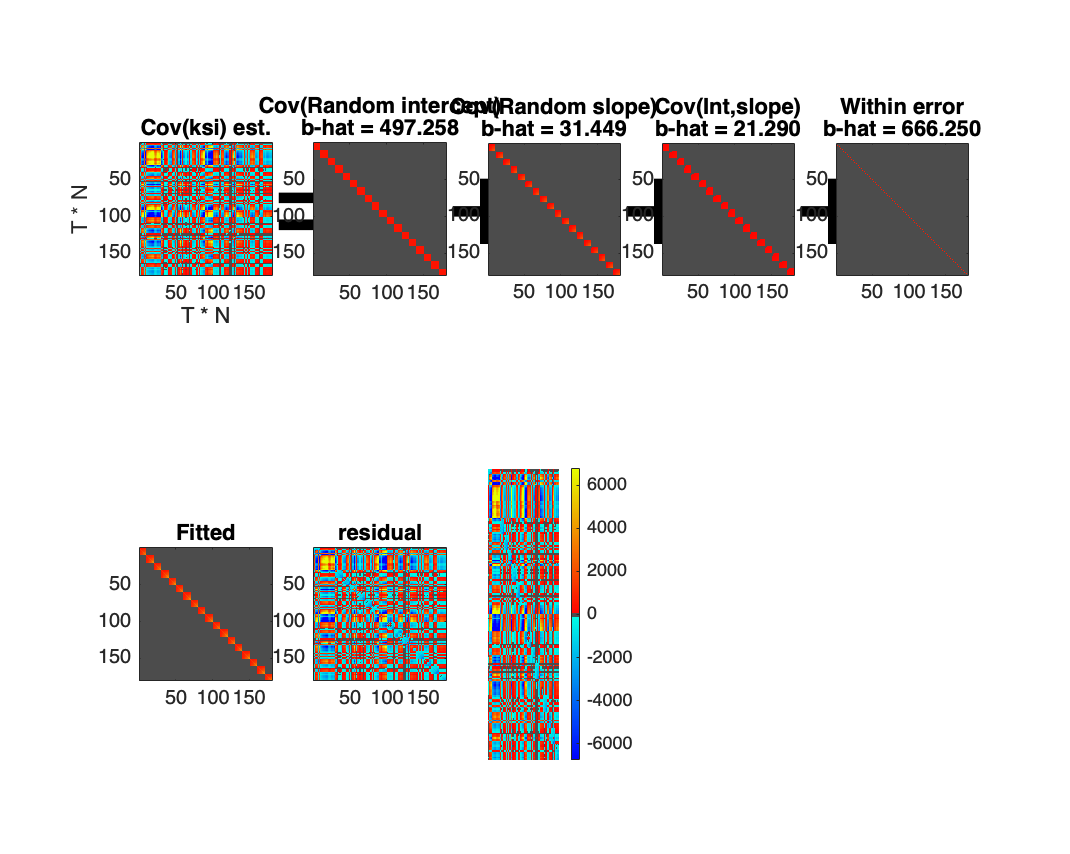

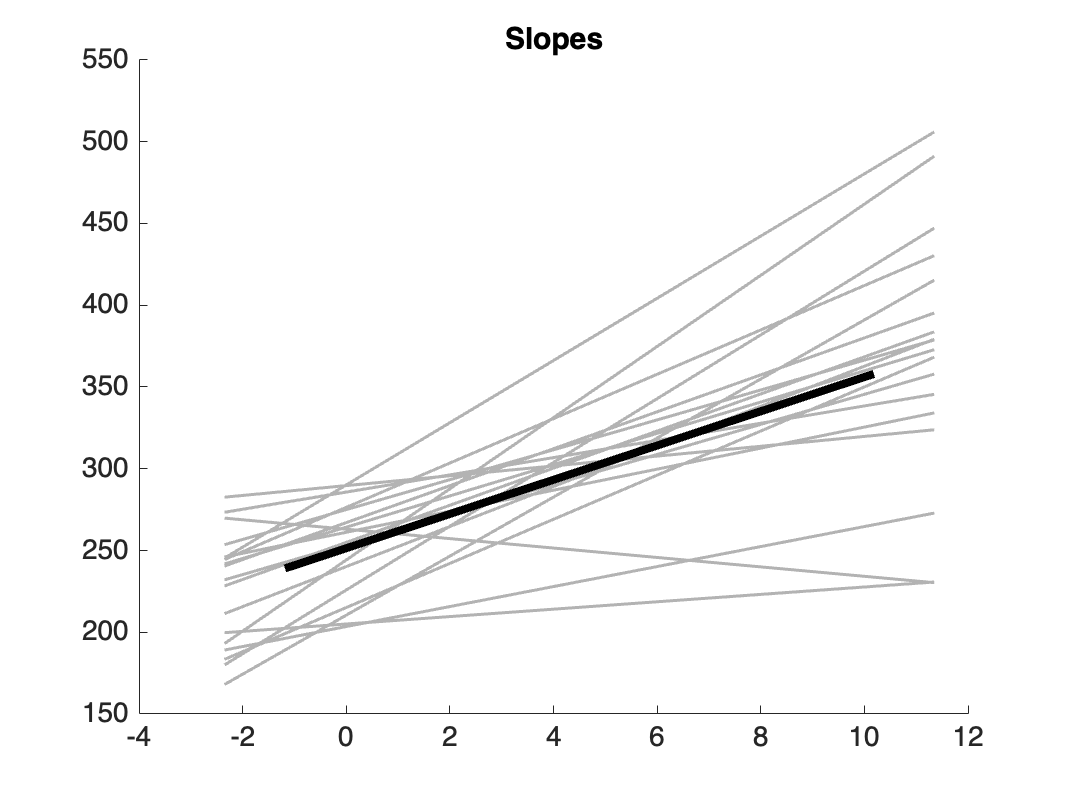


igls.m output report:
---------------------------------------
Data:  10 observations x  18 subjects 
Fit Type: igls
AR(p) model: No
Converged: Yes
Max iterations:   5, Completed iterations:   1
Epsilon for convergence: 0.010000
Elapsed time: 0.45 s

Statistics: Tests of inference on fixed population parameters
Parameter	est.	t( 17)	p	
Intcpt.	251.405	39.55	0.000000	***
Slope1	10.467	7.06	0.000002	***


Statistics: Tests of significance on random effects (variances)
Parameter	est.	LRT	p	
Intcpt.	497.258	22.09	0.000000	***
Slope1	31.449	42.01	0.000000	***

---------------------------------------




igls_stats = igls(sleep_rt_cell, X1, 'plot', 'all');

### glmfit_multilevel

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  18, Predictors:   1
Outcome names: Intercept	Days	
Weighting option: weighted
Inference option: t-test

Other Options:
	Plots: Yes
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
Total time: 0.02 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	Intercept	Days	
Adj. mean	250.61	10.11	

2nd-level B01
	Intercept	Days	
Coeff	250.61	10.11	
STE	7.14	1.55	
t	35.09	6.53	
Z	8.21	4.54	
p	0.00000	0.00001	

________________________________________


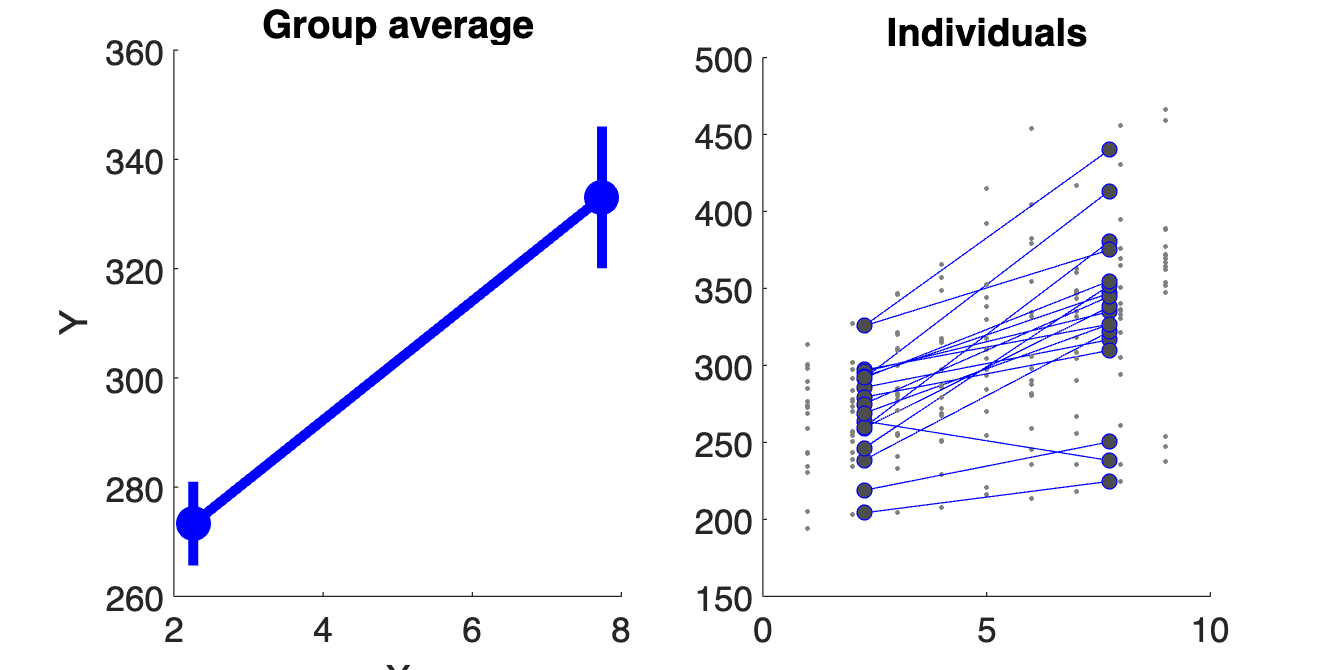

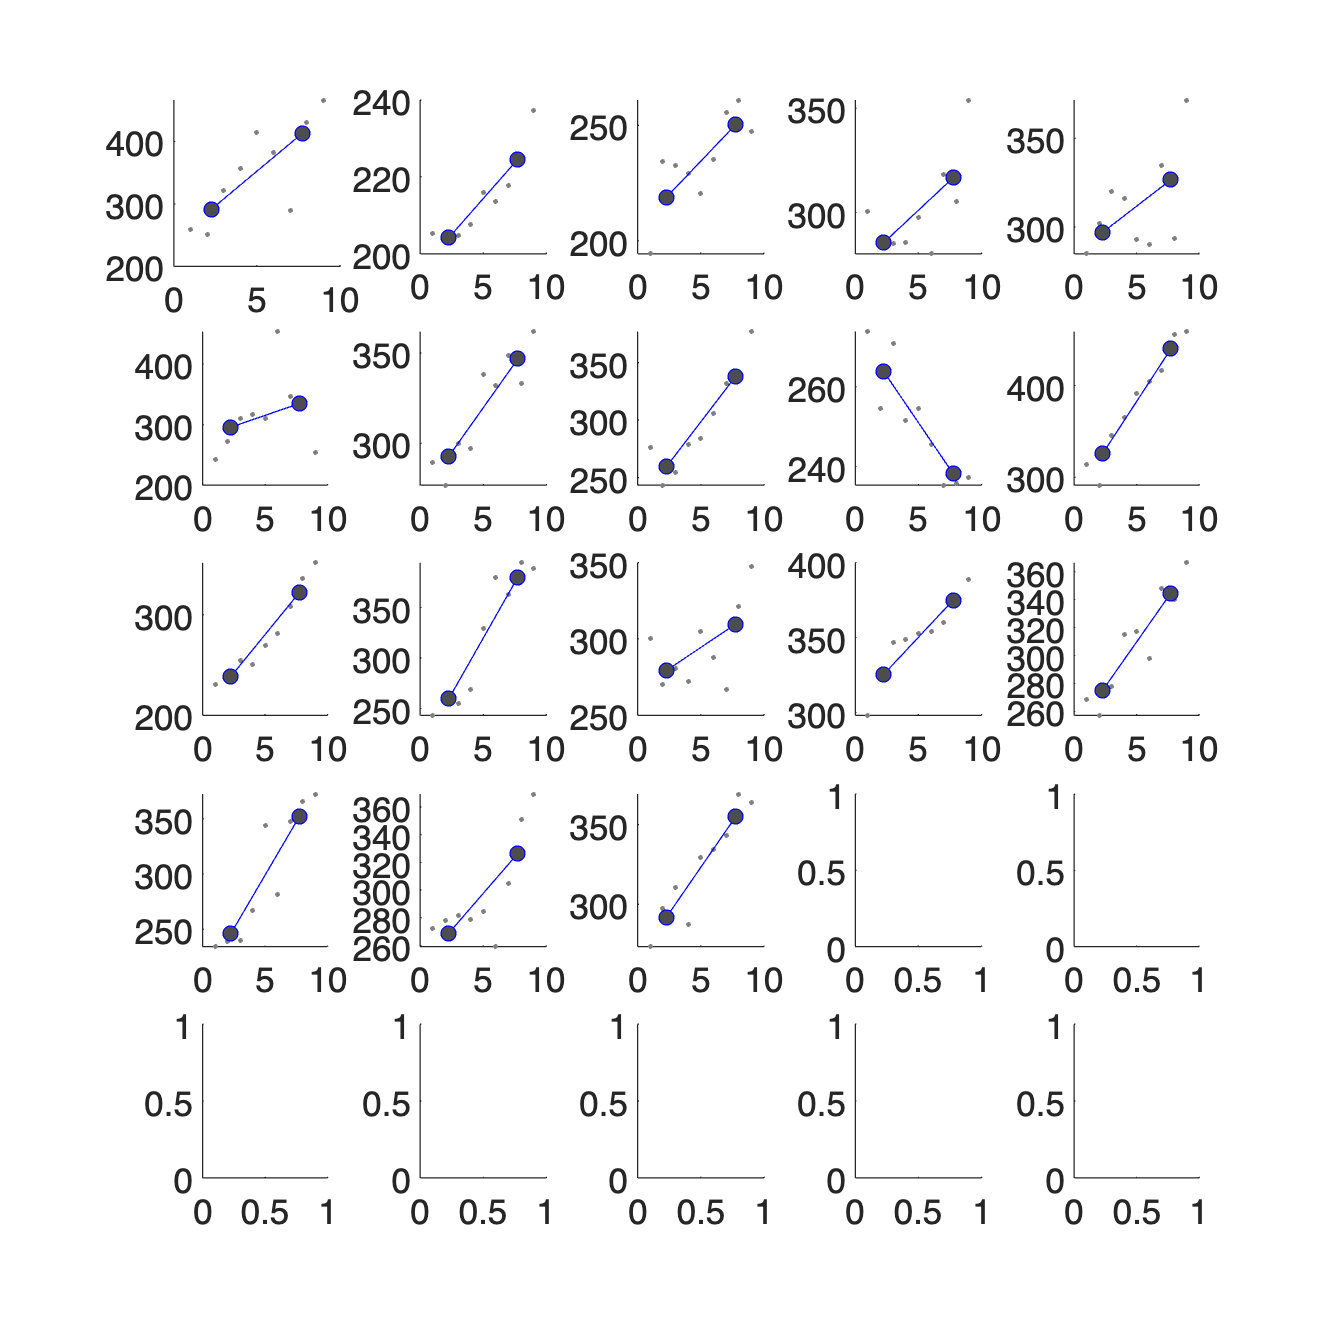

glmfit_stats = glmfit_multilevel(sleep_rt_cell, X1, [], 'names', {'Days'}, 'verbose', 'weighted', 'plot');